Projeto de ES020-Tópicos em Engenharia Mecatrônica I

Vinicius Allan da Silva RA:225295

##########################################################

Parte 0

##########################################################

clc;clear;close all force;
RA='225295';

    Nessa parte do codigo, nossa variavel RA e um ponteiro de vetor de char, onde o mesmo recebe a string do meu RA

    E necessario chamar a funcao digitosRA que transforma o vetor de char em um vetor de inteiros, assim, poderemos iterar sobre cada valor e fazer nossa logica conforme cada digito. 

    A funcao funciona da seguinte forma, um caracter tem uma representacao numerica, ou seja, numa string, o valor '0' tem valor 48 em seu endereco, entao basta ser subtraido 48 para chegarmos no numero em decimal equivalente.

d=digitosRA(RA)

d =      2     2     5     2     9     5


Como pode ser visto no codigo acima, o valor d representa o vetor de numeros inteiros que teve origem no vetor de char com os RA.

Para facilitar a particao do codigo, foi feito uma funcao dados_problema que ira calcular os valores basicos que serao utlizado ao longo do projeto.

Os valores calculados serao o comprimento L da viga, o momento de aera da viga ao entorno do eixo Z, o momento fletor M0, e as dimensoes b e h.

Todas essas variaveis serao em funcao do array d.

[L,Izz,M0,b,h]=dados_problema(d)

L = 95

Izz = 0.1913

M0 = 22000

b = 0.5400

h = 1.6200

Com isso, obtemos nossos primeiros valores que serao usado ao longo do projeto, L=95, Izz=0.1913, M0=22000, b=0.5400,h=1.62.

##########################################################

Parte 1

##########################################################

E=210e9;
P=M0/L;
x=0:0.1:L;

Declaramos algumas constantes que tambem serao utilizadas para os calculo das proximas funcoes, nosso modulo de elasticidade tem valor E=210e9.

E nossa forca externa P depende de M0 e L.

Foi necessario declar o x para que pudessemos plotar o grafico no valor da vida de 0 a L.

Mz=momento(P,L,M0);

a funcao momento, nos retorna um vetor Mz com diversos pontos ao longo da viga calculado pela funcao momento.

plot(x,Mz,':b');
hold on;

Para fazermos a mesma funcao, mas agora usando a singularidade e a function handler, declaramos um novo Mz, mas agora como function handler.

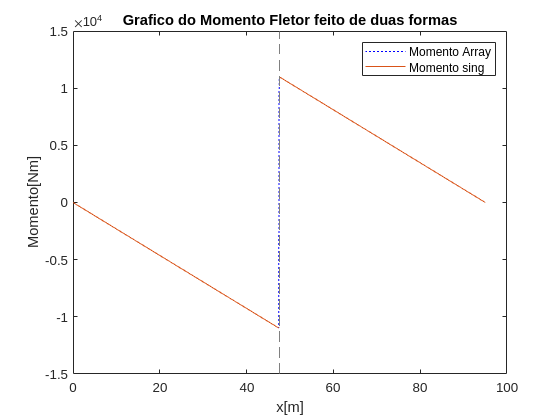

Mz=@(x) P*L-M0-P*x+M0*sing((x-L/2),0);
fplot(Mz,[0 L]);
hold off;
title('Grafico do Momento Fletor feito de duas formas')
xlabel('x[m]');
ylabel('Momento[Nm]');
legend('Momento Array','Momento sing');

Mz_inv=@(x) -P*L-M0-P*x+M0*sing((x-L/2),0)

Mz_inv = function_handle with value:
    @(x)-P*L-M0-P*x+M0*sing((x-L/2),0)


x_Mz_max=fminbnd(Mz_inv,0,90)

x_Mz_max = 47.5000

O modulo do momento fletor e maximo para o valor de x igual a x=47.5.

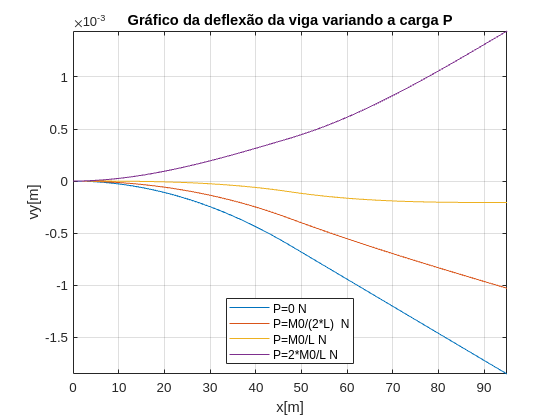

deflexao(M0,L,Izz,E);

tensao_graph(L,M0,h,Izz)

Discussao parte 1: Como os graficos foram criados? O primiero grafico do momento fletor por partes, foi criado atraves da iteracao sobre um vetor de tamanho fixo, a qual fomos iterando sobre cada posicao do vetor e calculando o momento para aquele ponto e verificando se a parcela da singularidade teria efeito naquele ponto, ou seja, o primeiro grafico foi plotado baseado num vetor de pontos discretizado e calculado separadamente. No mesmo grafico, foi plotado em cima a mesma funcao momento, porem, feita de uma forma diferente, declaramos ela atraves de um function handler, e a verificacao da singularidade foi feita atraves da funcao sing que ja retorna o valor caso ele seja considerado no calculo. A function handler nao tem pontos pre definidos, ela interpreta a funcao como se ela fosse uma funcao continua.

O grafico da deflexao foi feito usando a function handler, definimos diversos valores de P e plotamos um em cima do outro com a ajuda do hold on, como o a function handler nao e um vetor de ponto, precisamos definir nosso intervalo de 0 a L para ela plotar no range desejado.

O grafico da tensao foi feito utilizado a funcao meshgrid e Surf, a funcao meshgrid monta uma malha de pontos baseado nos valores do vetor de h, e do vetor de momento, conforme explicado dentro da funcao. atraves dessa malha de ponto, obteve-se uma matriz calculada apartir de todos os pontos da malha, essa matriz e plotada usando a funcao surf, forçamos a visualizacao na vista 2 para melhor ver o grafico da tensao. 

Qual o incremento utilizado na discretizacao das variaveis? Utilizei 0.1 como incremento para fazer os graficos apesar de tentar fazer com um incremento menor de 0.01, meu processador estava com dificuldade em processar todos os graficos e o valor de 0.1 foi o mais razoavel possivel sem perder qualidade.

Unidades: Momento fletor [Nm], Deflexao [m], Tensao[N/m2]. O idela e trabalhar sempre com a mesma unidade para as mesmas grandezas, para que nao haja confusao.

##########################################################

Parte 2

##########################################################

raiz=grafico_extremidade(L,M0,E,Izz)

Discussao: Conforme explicado na funcao de deflexao em funcao de P, a funcao de busca de raiz utilizada foi a funcao fzero, que necessita de um function handler e tem como opçao, um valor inicial para começar a busca. A funcao passada foi a funcao de deflexao em funcao de P, e para evitar processamento, passei um valor de busca inicial baseado na visualizacao do grafico plotado. Percebi que o zero tinha um valor x proximo de 250, entao esse foi meu chute inicial. O valor retornado foi x=260.5263. Os resultados coincidem com os valores do grafico, ja que visualmente, o valor da deflexao nula parece estar proxima de 260.

##########################################################

Parte 3

##########################################################

deflexao_maxima(M0,L,E,Izz);

Discussao: Foi utilizada a funcao fmincon, isso porque por se tratar de uma funcao que explode no +infinito e no -infinito. Como o objetivo era achar maximos e minimos locais, com a funcao fmincon, foi possivel limitarmos valores de busca entre 0 e L no x para que nosso resultado fosse encontrado, para isso, fizemos nosso lb=0 e ub=L. 

Os valores encontrados concidem com os valores visuais no grafico, ja que o maximo se encontra bem perto da extremidade esquerda e o minimo bem perto da extremidade direita.

####################################################################################################################################

Parte 4

####################################################################################################################################

g=9.81;
A=b*h;
rho=7850;
w0=rho*A*g;
P=M0/L;
A=[L 1 0;(3*L)/2 1 0;-1 0 -1];
b=[((w0*(L^2)/2)-M0);(w0*((3*L/2)^2)/2-M0-P*((3*L)/2)-L);(-w0*((3*L)/2)+P)];
x=A\b;
A

A =    95.0000    1.0000         0
  142.5000    1.0000         0
   -1.0000         0   -1.0000


x

x = 1.0e+08 *

    0.0800
   -4.5595
    0.0160


b

b = 1.0e+08 *

    3.0397
    6.8393
   -0.0960


w0=0;
b=[((w0*(L^2)/2)-M0);(w0*((3*L/2)^2)/2-M0-P*((3*L)/2)-L);(-w0*((3*L)/2)+P)];
x=A\b;
A

A =    95.0000    1.0000         0
  142.5000    1.0000         0
   -1.0000         0   -1.0000


x

x = 1.0e+04 *

   -0.0697
    4.4190
    0.0465


b

b = 1.0e+04 *

   -2.2000
   -5.5095
    0.0232


O sistema de equaçoes lineares devem ser primeiro separados em variaveis e constantes, ou seja, acharmos nossa matriz {A}, {x} e {b}, as constantes foram separadas e as variaveis Ra, Ma e Rd sao os resultados da matrix {x}.

Para resolver o sistema linear, o melhor metodo e fazendo a inversao da matriz A e multiplicando pela matriz b, ou seja {x}={A}(-1).{b}, porem, quando se trata de matriz, o operando \ e mais indicado para fazer a inversao da matriz. Com isso obteremos:

A=[95 1 0;142.5 1 0;-1 0 -1]

Para w0=rho*A*g;

b=10(-8).[3.0397;6.8393;-6.0960]

x=10(-8)[0.08;-4.5595;0.016]

Para w0=0;

b=10(4).[-2.2;-5.5095;0.0232]

x=10(4)[-0.0697;4.4190;0.0465]

#########################################################################################

Corpo das funcoes

#########################################################################################

funcao: digitosRA(RA)

function [d]=digitosRA(RA)
    %Essa funcao recebe como parametro uma string RA a qual ira vir 6
    %digitos em formato de char, entao no inicio, criamos um vetor com 6
    %posicoes inicialmente zerado, e pegamos cada valor da string em char e
    %substraimos 48 para chegarmos no valor em inteiro que nos interessa
    d=[0 0 0 0 0 0];
    d(1)=RA(1)-48;
    d(2)=RA(2)-48;
    d(3)=RA(3)-48;
    d(4)=RA(4)-48;
    d(5)=RA(5)-48; 
    d(6)=RA(6)-48;
    %O vetor d e retornado
end

funcao: dados_problema(d)

function [L,Izz,M0,b,h]=dados_problema(d)
    %Essa funcao calcula algumas variaveis que serao importante e que descrevem a viga.
    %Recebe o parametro d, e apartri dele calcula as variaveis de saida.
    %Caso o RA contenha digitos 0 na posicao 5 e 6, deve se fazer L=5.
    %E retornado os valores L,Izz,M0,b,h
    if(eq(d(5),0) && eq(d(6),0))  
        L=5;
    else
        L=10*d(5)+d(6);
    end
    b=10*d(3)+2*d(4);
    b=b*(0.01);
    h=3*b;
    M0=10*d(1)+d(2);
    M0=M0*1000;
    Izz=(b*(h^(3)))/12;
end

funcao: sing(x,n)

function y = sing(x,n) 
    %singularity function y = <x-a>^n 
    %essa funcao calcula de forma eficiente os casos de singularidade. A
    %singularidade tem a pecularidade ser fazer uma funcao ficar
    %descontinua, e para fazer isso, o codigo recebe a diferenca existente
    %dentro das <>, se ela for negativa, retorna 0, pois a parcela nao tem
    %efeito, se for positiva, faz o calculo.Porem se o numero do expoente
    %for menor que 0, retorna 0 tambem.
    %o valor retornado em y, corresponde a diferença passada elevada ao
    %expoente.
    if n>=0 
        y = x.^n.*(x>=0); 
    else 
        y = 0*x; 
    end 
end

funcao: momento(P,L,M0)

function[Mz]=momento(P,L,M0)
   %Grafico de momento que recebe P,L,M0 como parametro e retorna o vetor
   %Mz calculado para pontos discretizados de 0 a L.
   %A toda etapa fazemos uma verificacao para ver se o ponto i ja inclui a
   %parcela da singularidade dos calculos, caso positivo, a forma muda.
   x=0:0.1:L;
   tam=length(x);
   Mz=1:tam;
   for i=1:tam
       if(i<(tam/2))
           Mz(i)=P*L-M0-P*x(i);     
       else
            Mz(i)=P*(L-x(i));
       end
   end
end

funcao: deflexao(M0,L,Izz,E)

function []=deflexao(M0,L,Izz,E)
    %Essa funcao foi criada para organizar a secao da plotagem do grafico
    %de deflexao, ela recebe M0,L,Izz e E para fazer os calculos e define
    %diversos P ao longo das plotagens.
    %a deflexao vy e declarada conforme o P atual e utiliza a funcao sing
    %para os calculos da singularidade.
    P=0;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    figure;
    fplot(vy,[0 L]);
    xlabel('L[m]');
    ylabel('vy [m]');
    hold on;
    grid on;
    P=M0/(2*L);
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    P=M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    P=2*M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    fplot(vy,[0 L]);
    legend('P=0 N','P=M0/(2*L)  N','P=M0/L N','P=2*M0/L N','location','best');
    hold off;
    title('Gráfico da deflexão da viga variando a carga P');
    xlabel('x[m]');
    ylabel('vy[m]');
end

funcao: tensao_graph(M0,L,h,Izz)

function []=tensao_graph(M0,L,h,Izz)
    %funcao de tensao, recebe M0,L,h,Izz, ela calcula o valor de P usando
    %M0 e L passados e define o valor da altura da viga indo de -h/2 a h/2
    %com passo de 0.1, Tambem e calculado o vetor Mzz com os pontos para
    %geracao do grafico de superficie.E feito um meshgrid para juntas os
    %pontos numa superficie 'x' e y, e as variaveis X e Y ja sao resultados
    %das juncoes dos pontos.E calculado a tensao T em funcao de X e Y, e a
    %figura e plotada para visualizacao
    P=M0/L;
    y=-(h/2):0.1:h/2;  
    Mzz=momento(P,L,M0);
    [X,Y]=meshgrid(Mzz,y);
    T=-X.*Y/Izz;
    figure;
    x=0:0.1:L;
    surf(x,y,T);
    shading interp;
    title('Grafico de superficie da tensao na viga com a vista de topo')
    xlabel('x[m]');
    ylabel('h[m]');
    zlabel('Z');
    view(2);
end

funcao: grafico_extremidade(L,M0,E,Izz)

function [raiz]=grafico_extremidade(L,M0,E,Izz)
    %Nessa funcao, recebemos L,M0,E e Izz como parametros e definimos a
    %deflexao para um valor de x constante, igual a L, que e a extremidade
    %direita, e fazemos o P como variavel da funcao. A funcao e plotada num
    %intervalo de 0 a P=2M0/L. Utiliza-se a funcao fzero de busca das
    %raizes para achar o valor de P para qual a funcao tem a deflexao nula.
    %O valor de P e retornado como raiz.
    cte=(1/(E*Izz));
    vy=@(P)  (cte)*((P.*L-M0)*((L^2/2))-((P./6)*(L^3))+(M0/2)*(L-L/2)^2);
    figure;
    fplot(vy,[0 (2*M0/L)]);
    hold on;
    raiz=fzero(vy,250);
    plot(raiz,0,'dr');
    hold off;
    xlabel('P[N]');
    ylabel('Deflexao[m]');
    title('Valores da deflexao da viga em sua extremidade em funcao de P');
    legend('deflexao','deflexao nula','location','best')
end


funcao: deflexao_maxima(M0,L,E,Izz)

function []=deflexao_maxima(M0,L,E,Izz) 
    P=M0/L;
    vy=@(x) (1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    vy_inv=@(x) (-1/(E*Izz))*(((P*L)-M0)*((x.^2)/2)-((P*x.^3)/6)+(M0/2)*sing((x-(L/2)),2));
    figure;
    fplot(vy,[(0) (L)]);
    hold on;
    A=[];
    b=[];
    Aeq=[];
    beq=[];
    lb=0;
    ub=L;
    [min,fvy]=fmincon(vy,L,A,b,Aeq,beq,lb,ub);
    [min,fvy]
    plot(min,fvy,'*g');
    [max,fvy]=fmincon(vy_inv,0,A,b,Aeq,beq,lb,ub);
    [max,fvy]
    plot(max,fvy,'*g');
    x_nulo=fzero(vy,0);
    plot(x_nulo,vy(x_nulo),'sr');
    hold off;
    title('Grafico da deflexao para P=M0/L e seus valores maximos e minimos');
    xlabel('x[m]');
    ylabel('deflexao[m]');
    legend('deflexao','deflexao minimo','deflexao maximo','deflexao nula','location','best');
end